# Simplified model of house temperature behaviour

This livescript is a brief manual in support of the app ***housetemperature_and_behaviour.mlapp***.   This is a simple interface to understand the behaviour of simple thermal systems comprising some heat capacity, heat loss, heat supply and an external environment. The system has simple first order dynamics and users can observe the impact of simple parameter changes on this behaviour.

Later on, users may wish to explore the role of PI compensation for maintaining the hourse at a desirable temperature (see ***housetemperature_control.mlapp***).

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Engineering context

- Investigating the impact of parameter changes or open-loop analysis

- Interface and user interaction

## 1. Engineering context

We consider that house temperature ***T ****(deg)* can be represented as a simple thermal system model. Take the system to have thermal capacitcance ***C*** (J/deg), heat loss to the environment (***k*** W/deg), heat supply ***W*** (watts) and external temperature $T_e$ (deg). A simple model is then given from the differential equation:


$$C\frac{\textrm{dT}}{\textrm{dt}}+k\left(T-T_e \right)=W$$


As the basic model is a 1st order differential equation, it is common place to model these in time constant form.


$$\frac{C}{k}\frac{\textrm{dT}}{\textrm{dt}}+T=\frac{1}{k}\left(W+kT_e \right)\;\;\;\Leftrightarrow \;\;\;\;\tau \frac{\textrm{dv}}{\textrm{dt}}+v=T_{\textrm{ss}}$$


where the time constant $\tau =\frac{C}{k}$  gives an indicator of the convergence rate (typically about 3 time constants to be within 5% of steady-state) and $T_{\textrm{ss}} =\frac{1}{k}\left(W+kT_e \right)$ is the expected steady-state (with no disturbances). The bottom left figure shows the computation of these two parameters (see figure at end of this livescript for an illustration). The time constant is also included in the legend of the bottom right figure of the app for record keeping.

For convenience, the time scale is expressed in hours and the gain is expressed in deg/kW.

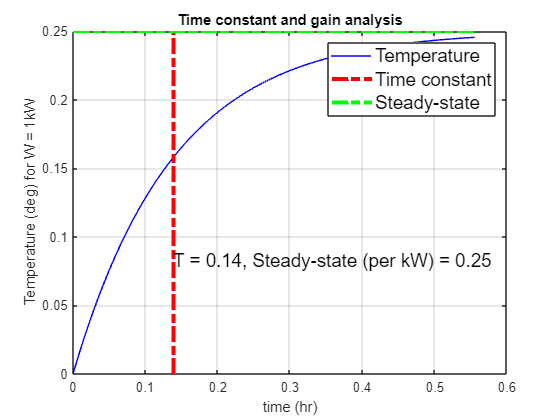

C=2*10^6;
k=4*10^3;
W = 10^3;
Te=0;
tau=C/k;
Tss=(W+k*Te)/k;
time = linspace(0,4*tau,201);
T = (1-exp(-time/tau))*W/k;
tau=tau/3600;

figure; clf
plot(time/3600,T,'b');
hold('on') ;
plot([tau,tau],[0,Tss],'r-.','linewidth',3)
plot([0,4*tau],[Tss,Tss],'g-.','linewidth',3);
kkk=legend('Temperature','Time constant','Steady-state');
set(kkk,'fontsize',14);
text(tau,Tss/3,['T = ',num2str(round(tau,2)),', Steady-state (per kW) = ',num2str(Tss)],'fontsize', 14);
title('Time constant and gain analysis')
xlabel('time (hr)');
ylabel('Temperature (deg) for W = 1kW')
grid('on');

hold('off');

## 2. Investigating the impact of parameter changes

We are particular interested in how parameter changes effect the temperature behaviour and may wish to ask questions such as the following.

- What happens if the house gets bigger (that is C is bigger)? How does this effect time constant/convergence rate and the steady-state?

- How does wall insulation (parameter k) affect the behaviour?

- How does the heat supply W affect behaviour?

- How does the external termperature and initial condition affect behaviour?

A general solution is know to take the form:

$T\left(t\right)=\left\lbrack T\left(0\right)-T_{\textrm{ss}} \right\rbrack e^{-\frac{t}{\tau }} +T_{\textrm{ss}}$ ;  $T_{\textrm{ss}} =\frac{1}{k}\left(W+kT_e \right)$;  $\tau =\frac{C}{k}$

so one can analyse this equation to determine the expected behaviours.

The user is encouraged to do some thought experiments on the above, and then use the app to validate their expectations. For example:

- Changing C changes the size of the house:

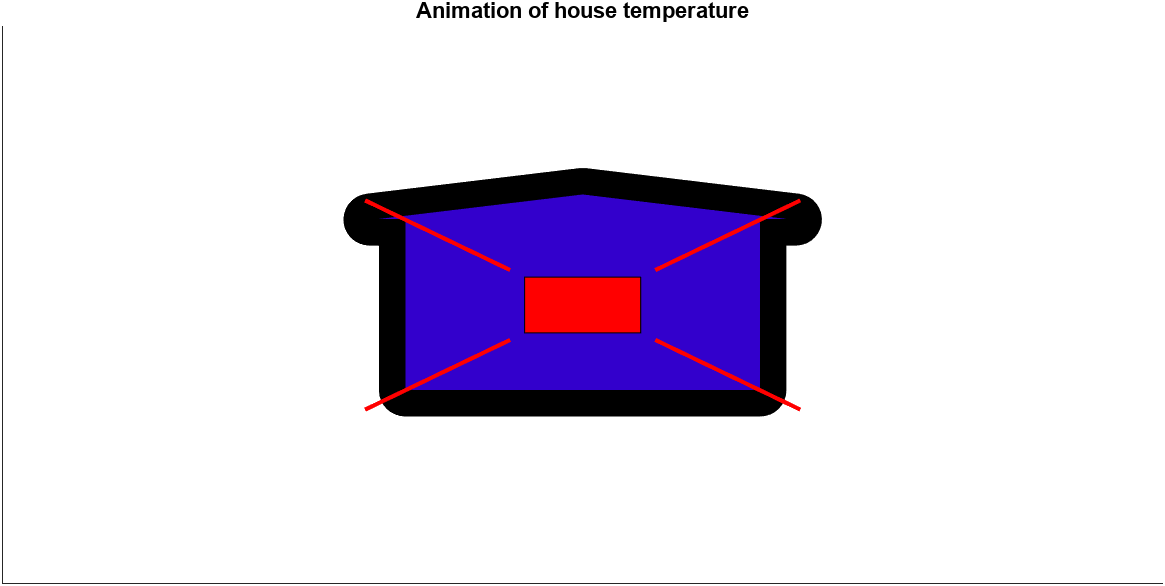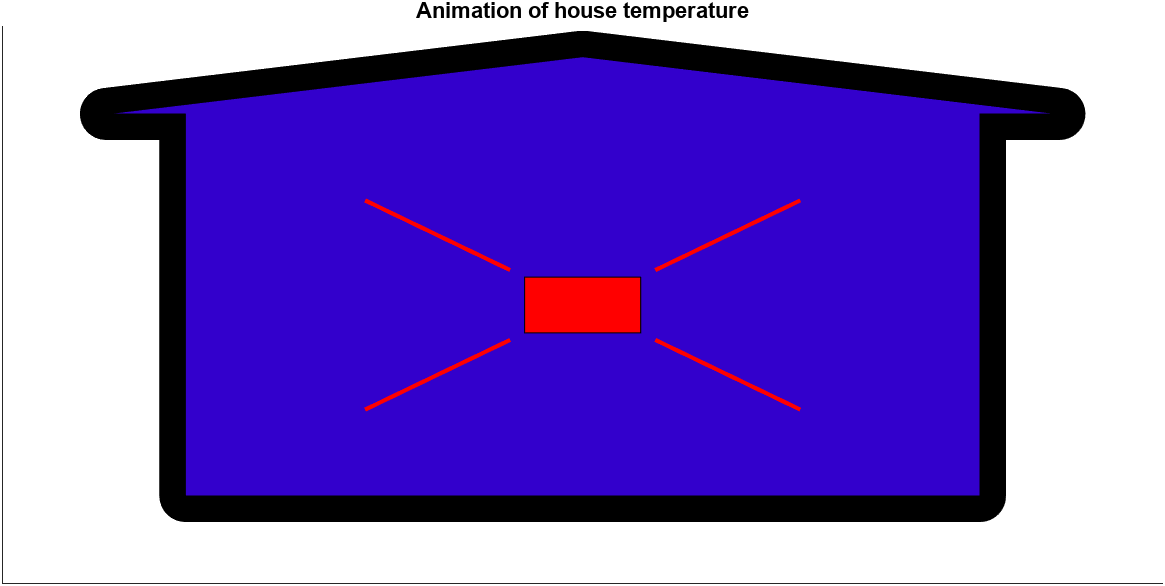

- Changing k changes the wall thickness (to represent heat loss) and changing W changes the red rectangle size ( to represent a larger or smaller fire).

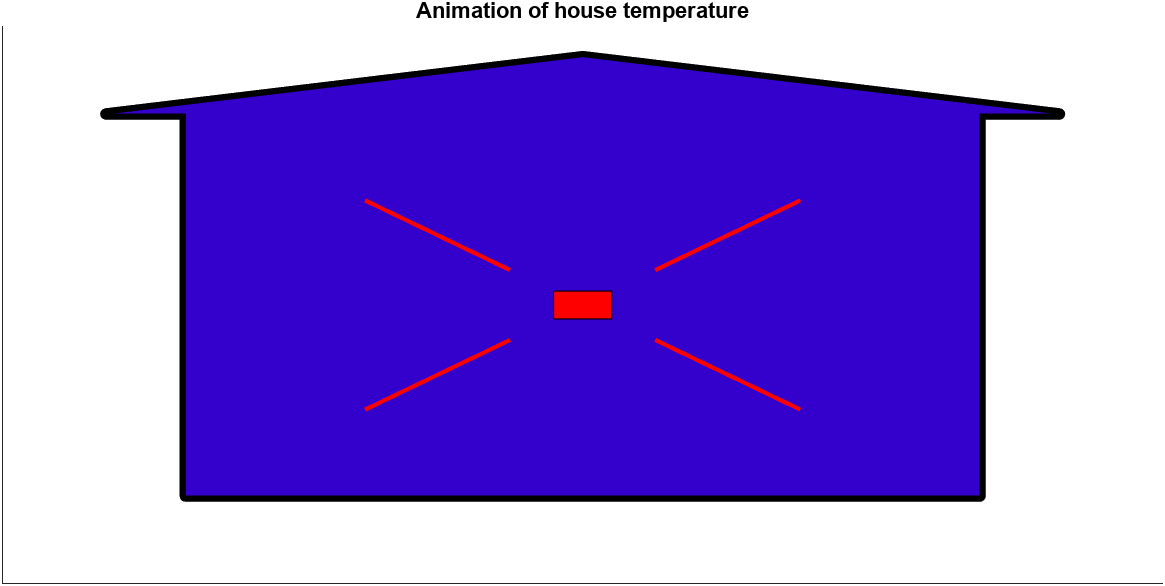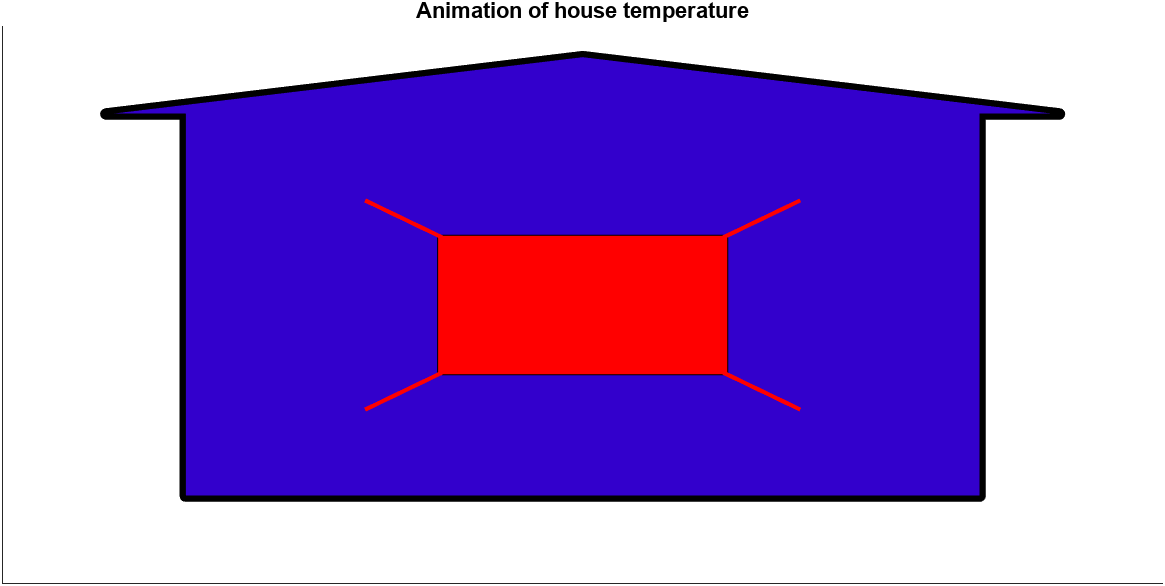

- Changing the temperature changes the colour (bright blue for cold, purple for warm and red for hot).

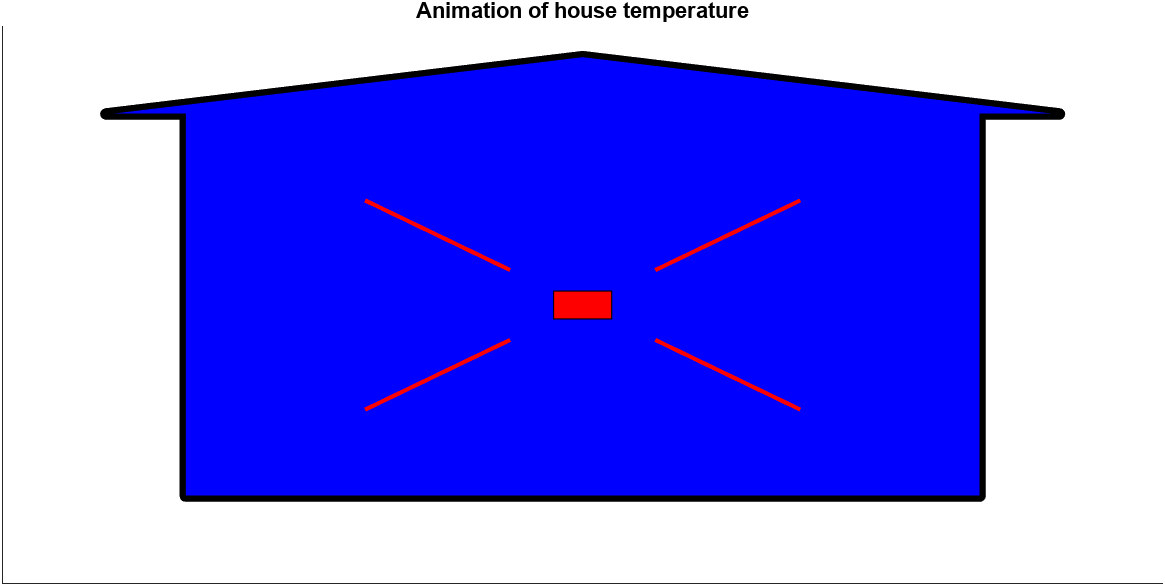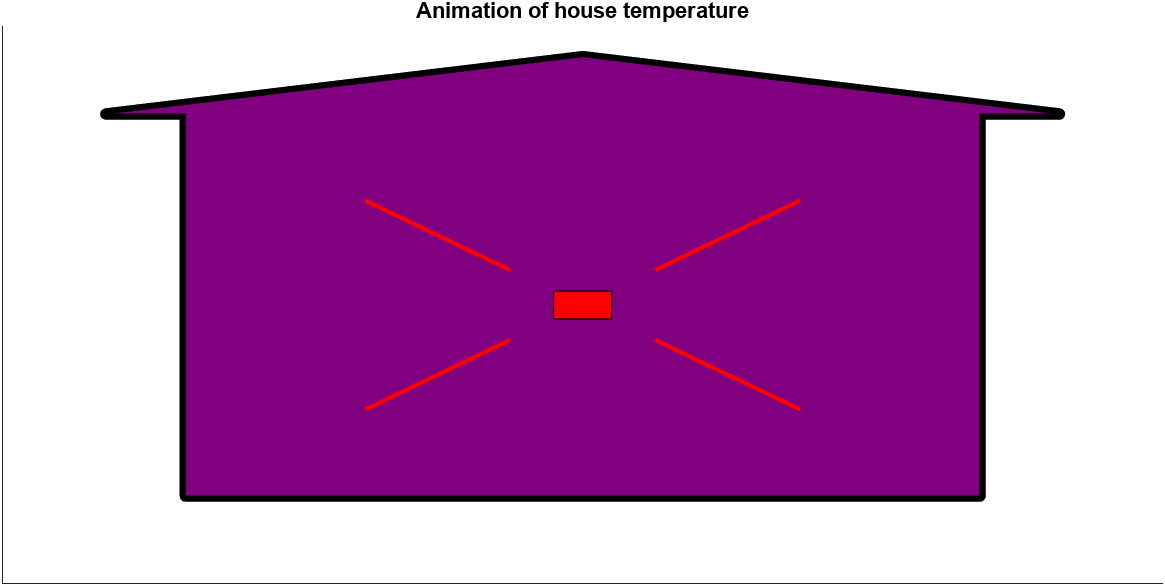

- Simulations with different parameter choices can be saved to allow systematic investigations. Below we only change the parameter k.

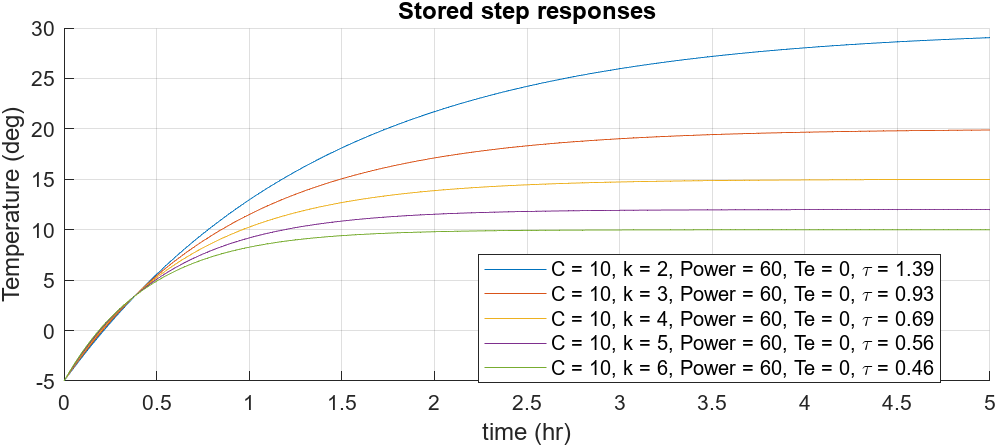

## 3. Interface and user interaction

The image below shows the app interface.  The use is largely self-explanatory. 

- The sliders allow the user to set up the desired simulation. 

- The image in the top right is updated as a slider is changed to represent the scenario.

- The animation runs for about 10 seconds to show the responses in the current scenario; this includes animation of the line plots and also the colour of the house to represent temperature changes.

- The animation can be switched off if desired to allow for faster investigations.

- The refresh button clears the bottom right figure so that a new set of investigations can be started.

Hence, users can run the simulation with various choices of parameters and overlay the results so they can build a picture and understanding of the impact of different changes.